% ODEの右辺の関数と真の解の関数の定義
f = @(t, y) y - t*t + 1.0;
g = @(t) (t+1).^2 - exp(t)/2; % この例の真の解

% 初期条件とパラメータ設定
a = 0;
b = 2;
alpha = 0.5;
N = 10;

% オイラー法の実行
[t, w, error] = eulerODE1(f, g, a, b, alpha, N);
fprintf(" %5.3f %11.7f %11.7f \n", t, w, error);

 0.000   0.2000000   0.4000000 
 0.600   0.8000000   1.0000000 
 1.200   1.4000000   1.6000000 
 1.800   2.0000000   0.5000000 
 0.800   1.1520000   1.5504000 
 1.988   2.4581760   2.9498112 
 3.452   3.9501281   4.4281538 
 4.866   0.0000000   0.0292986 
 0.062   0.0985406   0.1387495 
 0.183   0.2301303   0.2806266 
 0.333   0.3870225   0.4396874 


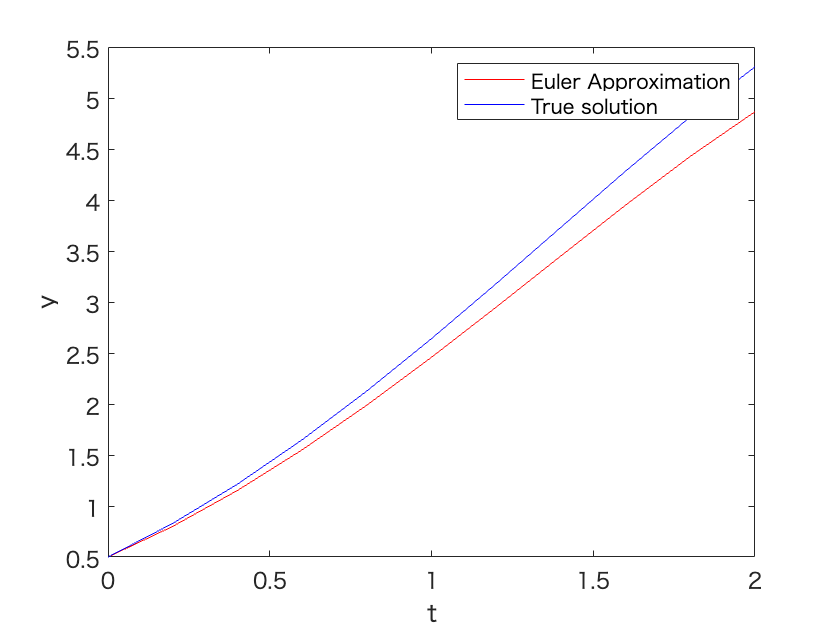


clf;
% 近似解と真の解のプロット
plot(t, w, 'r', t, g(t), 'b');
legend('Euler Approximation', 'True solution');
xlabel('t');
ylabel('y');

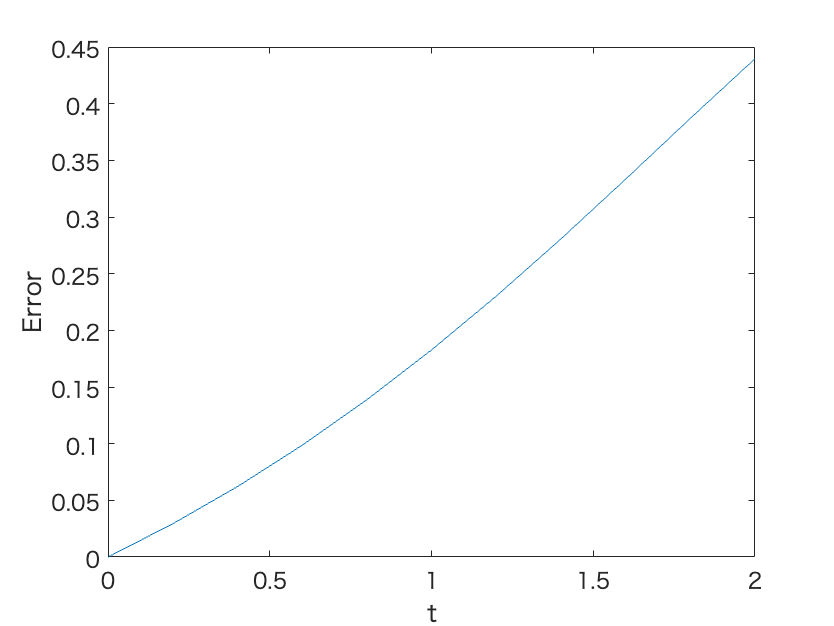


% 誤差のプロット
figure;
plot(t, error);
xlabel('t');
ylabel('Error');

% ODEの右辺の関数と真の解の関数の定義
f = @(t, y) y - t*t + 1.0;;
g = @(t) (t+1).*(t+1) - exp(t)/2; % この例の真の解は y = e^t - t - 1

% オイラー法の実行
[t, w, error] = eulerODE2(f, g);
fprintf(" %5.3f %11.7f %11.7f \n", t, w, error);

 0.000   0.2000000   0.4000000 
 0.600   0.8000000   1.0000000 
 1.200   1.4000000   1.6000000 
 1.800   2.0000000   0.5000000 
 0.800   1.1520000   1.5504000 
 1.988   2.4581760   2.9498112 
 3.452   3.9501281   4.4281538 
 4.866   0.0000000   0.0292986 
 0.062   0.0985406   0.1387495 
 0.183   0.2301303   0.2806266 
 0.333   0.3870225   0.4396874 



% 近似解と真の解のプロット
plot(t, w, 'r', t, g(t), 'b');
legend('Euler Approximation', 'True solution');
xlabel('t');
ylabel('y');


% 誤差のプロット
figure;
plot(t, error);
xlabel('t');
ylabel('Error');

function [t, w, error] = eulerODE1(f, g, a, b, alpha, N)
    % 入力：
    % f - ODEの右辺の関数
    % g - 真の解の関数
    % a, b - 時間区間 [a, b] の端点
    % alpha - a における初期値
    % N - [a, b] を等分割する整数
    
    % 出力：
    % t - 時間ベクトル
    % w - 近似解ベクトル
    % error - 真の解との誤差ベクトル
    
    h = (b-a)/N; % ステップ幅
    t = a:h:b; % 時間ベクトル
    w = zeros(1, N+1); % 近似解を格納するベクトル
    w(1) = alpha; % 初期値の設定
    
    % オイラー法
    for i = 1:N
        w(i+1) = w(i) + h*f(t(i), w(i));
    end
    
    % 真の解との誤差
    true_sol = g(t); % 真の解ベクトル
    error = abs(true_sol - w); % 誤差ベクトル
    
end

function [t, w, error] = eulerODE2(f, g)
    % 入力：
    % f - ODEの右辺の関数
    % g - 真の解の関数
    
    % 出力：
    % t - 時間ベクトル
    % w - 近似解ベクトル
    % error - 真の解との誤差ベクトル
    
    % ユーザーからの入力を受け取る
    a = input('Enter the start of the interval, a: ');
    b = input('Enter the end of the interval, b: ');
    alpha = input('Enter the initial value at a, alpha: ');
    N = input('Enter the number of steps, N: ');
    
    h = (b-a)/N; % ステップ幅
    t = a:h:b; % 時間ベクトル
    w = zeros(1, N+1); % 近似解を格納するベクトル
    w(1) = alpha; % 初期値の設定
    
    % オイラー法
    for i = 1:N
        w(i+1) = w(i) + h*f(t(i), w(i));
    end
    
    % 真の解との誤差
    true_sol = g(t); % 真の解ベクトル
    error = abs(true_sol - w); % 誤差ベクトル
    
end
